# Traitement du Signal - TD 5 

Signal Processing Toolbox

14/12/2022 

Déric Augusto França de Sales

Michelle Ferreira Martins

clc; close all; clear all;

## A) Echantillonnage d'un signal port

### 1. Détermination de la fréquence d'échantillonnage

Rf = 0.125; % resolution frequentielle
Fe = 8; % frequence d'echantillonnage

### 2. Elaborer le signal numérique x(n) obtenu par échantillonnage de x(t).

syms a
signal_continu = rectangularPulse(a), [-1 1];

$$signal\_continu = \mathrm{rectangularPulse}\left(-\frac{1}{2},\frac{1}{2},a\right)$$

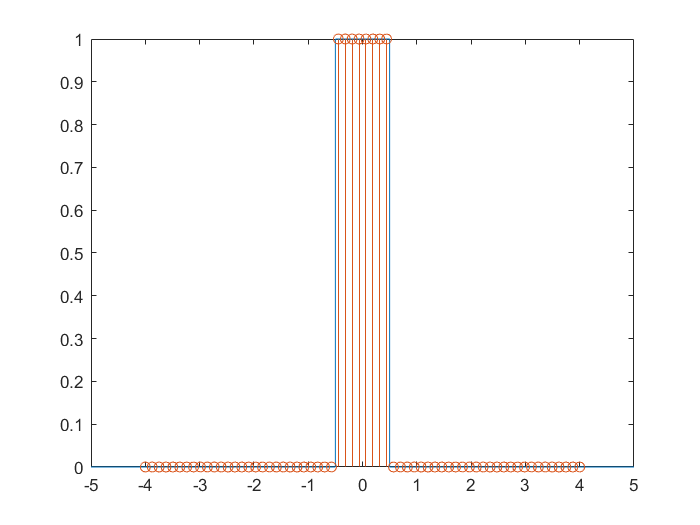

fplot(signal_continu) % signal porte continu d'amplitude 1 de largeur 1 seconde
hold on
x = linspace(-Fe/2, Fe/2, Fe/Rf);
y = [zeros(1, Fe/(2*Rf) - Fe/2), ones(1, Fe), zeros(1, Fe/(2*Rf) - Fe/2)];
stem(x, y) % signal porte discret d'amplitude 1 de largeur 1 seconde

%title('Signal porte échantillonée')

### 3. Calculer le spectre de x(n) par et tracer son spectre.

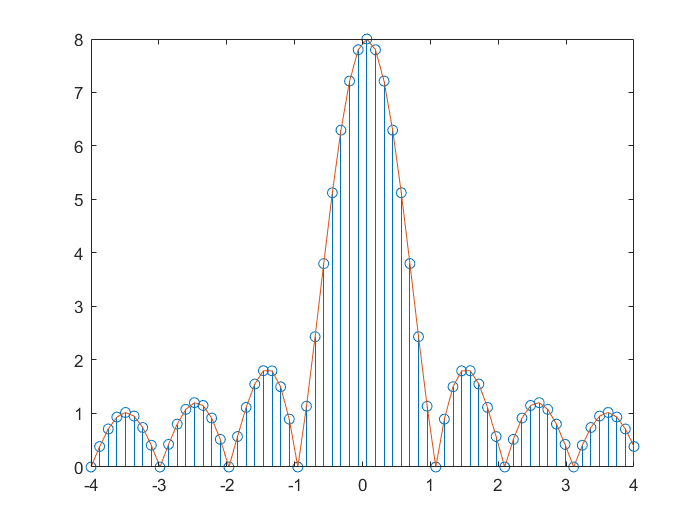

figure
z = fftshift(abs(fft(y)));
stem(x, z) % transformee de fourier discrete 
hold on
plot(x, z) % transformee de fourier continue

%title('Spectre du signal porte')

## Signal extra

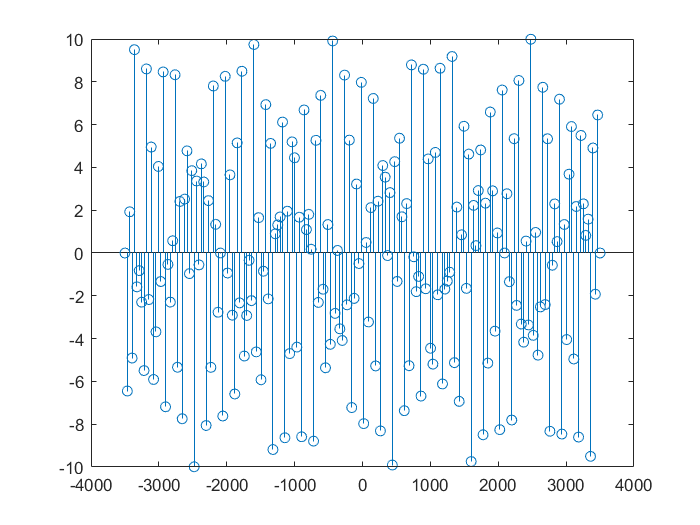

Fe_new = 7000;
Rf_new = 35;

x_new = linspace(-Fe_new/2, Fe_new/2, Fe_new/Rf_new);
y = 4*sin(2*pi*1500*x_new) + 6*sin(2*pi*3500*x_new);
figure
stem(x_new, y); 

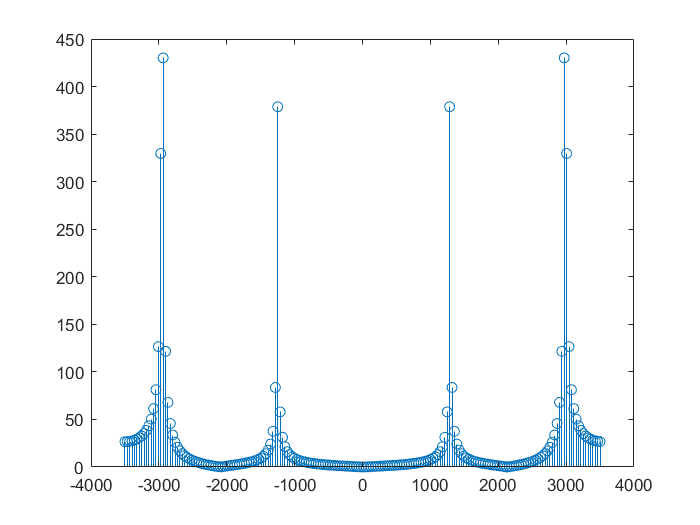

figure
z = fftshift(abs(fft(y)));
stem(x_new, z) 

## B) Traitement numérique d’un signal par filtrage IIR et FIR

1. Importe du fichier mesure.dat

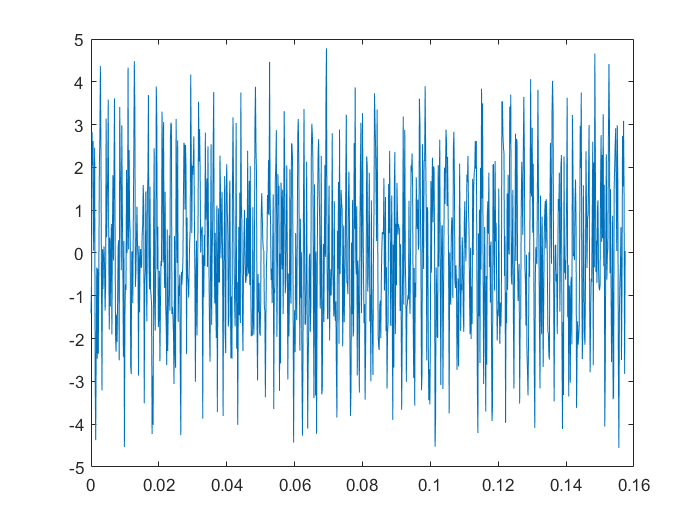

load ('mesure.dat');
t = mesure(1,:); % vecteur temps
x = mesure(2,:); % signal échantillonne
taille = length(x); % nombre de points
figure
plot(t,x) % Signal importe

%title('Signal importé')

2. Analyse du signal

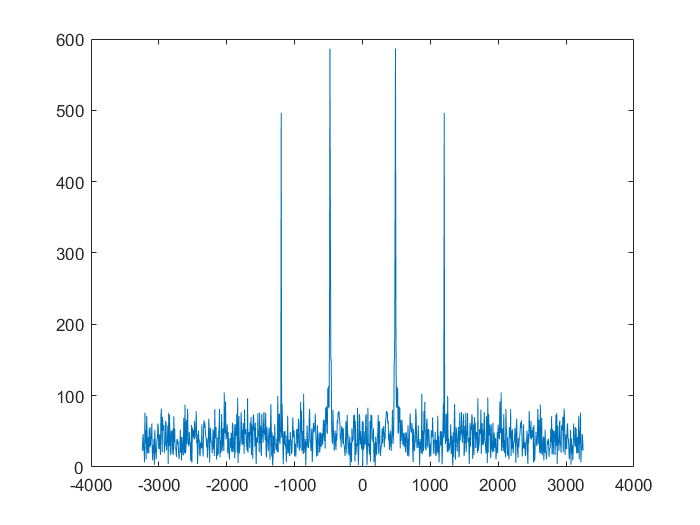

Te = mesure(1,2) - mesure(1,1); % periode d'echantillonnage
Fe = 1/Te; % frequence d'echantillonnage
duree = mesure(1,1024); % duree du signal

f = -Fe/2 : 1/duree : Fe/2;
y = fftshift(fft(x));
figure
plot(f,abs(y))

%title('Spectre du Signal') % FFT

3. Filtrage du signal

Technique RII

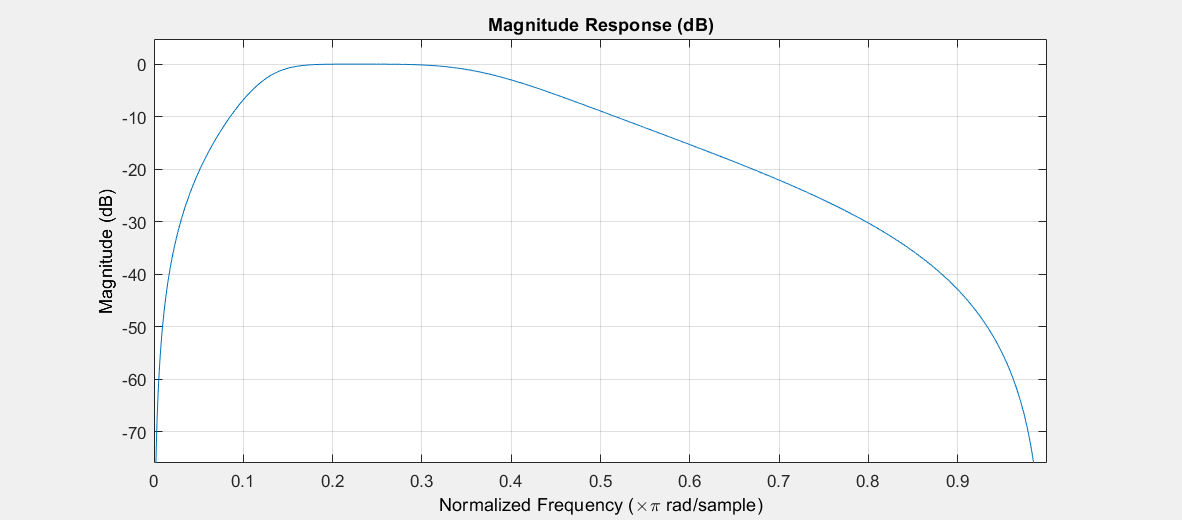

order_RII = 2; % filter's order
pass_band_RII = [400 1300]*2/Fe; % frequency range

[b, a] = butter(order_RII, pass_band_RII);

fvtool(b,a); % generates bode graphs (magnitude and phase),

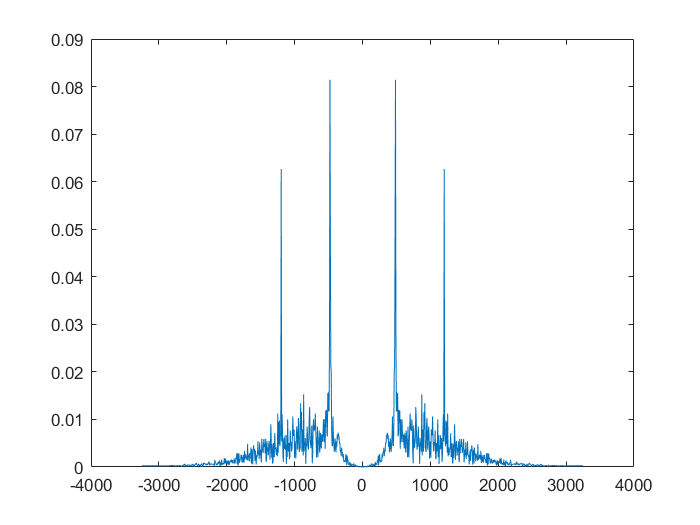

%pole and zero diagrams and others
fRII = filter(b, a, x);
fft_RII = fftshift(abs(fft(fRII))/Fe);
figure
plot(f, fft_RII)

%title('FFT du signal après le ftilrage RII')

Technique RIF

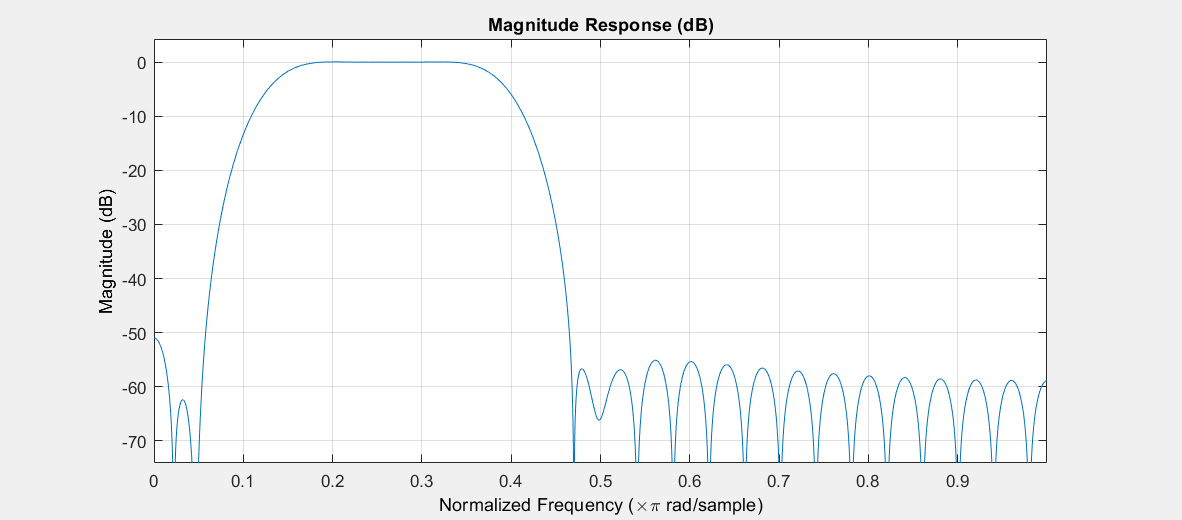

order_RIF = 50; % filter's order
pass_band_RIF = [400 1300]*2/Fe; % frequency range

RIF = fir1(order_RIF, pass_band_RIF);
fvtool(RIF, 1); % generates bode graphs (magnitude and phase), 

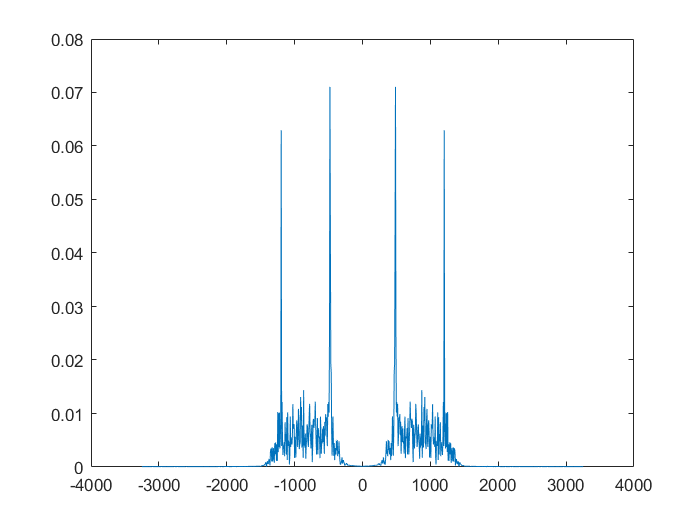

%pole and zero diagrams and others
fRIF = filter(RIF, 1, x);
fft_RIF = fftshift(abs(fft(fRIF))/Fe);
figure
plot(f, fft_RIF)

%title('FFT du signal après le filtrage RIF')